** 网格剖分方法**

第一步，清理环境

clc %清空屏幕
clear %清空工作区

第二步，输入参数

%波长(nm)
wavelength = [468.36;556.26;673.46;819.88;877.97] %蓝光、绿峰、红谷、红外、红外

wavelength =   468.3600
  556.2600
  673.4600
  819.8800
  877.9700


%样品配置
leaf = 'corn';%叶片品种
surface = 'up';%叶片正反面
num_leaf = 6;%叶片数量
num_measure = 2;%muesure.xlsx_sheet2
% min_angle=15;%最小检测角
rho0 = 0.5;%粗糙度初始值
k0 = 0.5;%漫反射系数初始值
n0 = 3;%折射率初始值

第三步，读取excel数据

%输入白板/样本测量方案
x_data_angle = readmatrix('measure.xlsx','Sheet',strcat('sheet',num2str(num_measure)),'range','B2:D77')%测量角度的配置数据

x_data_angle =      0    95    15
     0    95    20
     0    95    30
     0    95    40
     0    95    50
     0    95    60
     0    95    70
     0    95   110
     0    95   120
     0    95   130


%输入白板测量结果——已与角度配置匹配
wb_data_intensity = readmatrix('intensity_whiteboard.xlsx','Sheet',strcat('sheet',num2str(num_measure))) %白板的光强测量数据

wb_data_intensity = 1.0e+04 *

    0.0199    0.2699    0.0199    0.2695    0.0199    0.2697    0.0199    0.2688    0.0199    0.2684    0.0199    0.2671    0.0199    0.2665    0.0199    0.2678    0.0199    0.2685    0.0199    0.2688    0.0199    0.2697    0.0199    0.2702    0.0199    0.2704    0.0199    0.2728    0.0199    0.2729    0.0199    0.2720    0.0199    0.2718    0.0199    0.2722    0.0199    0.2721    0.0199    0.2718    0.0199    0.2706    0.0199    0.2698    0.0199    0.2694    0.0199    0.2702    0.0199    0.2705
    0.0200    0.0151    0.0200    0.0142    0.0200    0.0142    0.0200    0.0135    0.0200    0.0130    0.0200    0.0120    0.0200    0.0110    0.0200    0.0123    0.0200    0.0128    0.0200    0.0133    0.0200    0.0137    0.0200    0.0142    0.0200    0.0145    0.0200    0.0165    0.0200    0.0168    0.0200    0.0159    0.0200    0.0161    0.0200    0.0161    0.0200    0.0164    0.0200    0.0157    0.0200    0.0147    0.0200    0.0138    0.0200    0.0132    0.02

%逐个编号输入样本测量结果——需要筛选角度
for i=1:num_leaf
    leaf_xlsx = strcat(leaf,num2str(i),'-',surface,'.xlsx');
    reflect_data_intensity(:,:,i) = readmatrix(leaf_xlsx,'Sheet','Sheet1');%样本i的光强测量结果
end
%输出样本原始测量数据
reflect_data_intensity

reflect_data_intensity = reflect_data_intensity(:,:,1) =

   1.0e+04 *

    0.0199    0.2764    0.0199    0.2765    0.0199    0.2767    0.0199    0.2766    0.0199    0.2759    0.0199    0.2761    0.0199    0.2759    0.0199    0.2757    0.0199    0.2757    0.0199    0.2762    0.0199    0.2762    0.0199    0.2766    0.0199    0.2771    0.0199    0.2771    0.0199    0.2774    0.0199    0.2771    0.0199    0.2767    0.0199    0.2763    0.0199    0.2760    0.0199    0.2761    0.0199    0.2758    0.0199    0.2758    0.0199    0.2763    0.0199    0.2763    0.0199    0.2760    0.0199    0.2762    0.0199    0.2762    0.0199    0.2765    0.0199    0.2765    0.0199    0.2765    0.0199    0.2764    0.0199    0.2769    0.0199    0.2767    0.0199    0.2767    0.0199    0.2766    0.0199    0.2761    0.0199    0.2763    0.0199    0.2765    0.0199    0.2774    0.0199    0.2775    0.0199    0.2767    0.0199    0.2766    0.0199    0.2769    0.0199    0.2762    0.0199    0.2763    0.0199    0.2760    0.01

第四步，确定入、反射光测量配置，得到相关的空间向量和角度（测量配置）

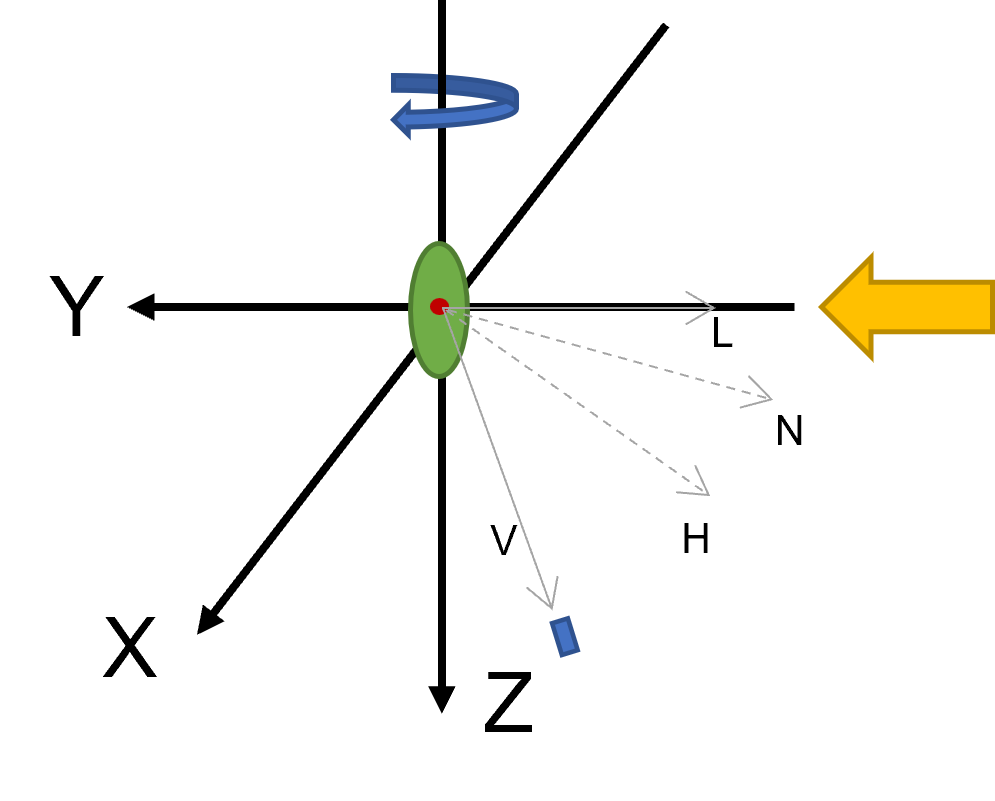

%不考虑圆环的转动，仅研究单个平面光的反射特性
%确定测量配置索引
x_data_orign = zeros(size(x_data_angle,1),19);
x_data_orign(:,1:3) = x_data_angle;
for i = 1:size(x_data_orign,1)
    phi_ring = x_data_orign(i,1); %圆环平面角度
    angle_leaf = x_data_orign(i,2); %叶片角度
    angle_view = x_data_orign(i,3); %测量器角度
    theta_incidence = 95-angle_leaf; %由于叶片95度为垂直入射，计算入射角（入射向量和叶片法向量）
    x_data_orign(i,4) = theta_incidence;%入射角（入射向量和叶片法向量的夹角）
    %L
    %入射方向单位向量
    x_data_orign(i,7) = 0;
    x_data_orign(i,8) = -1;
    x_data_orign(i,9) = 0;
    %N
    %叶片的单位法向量
    x_data_orign(i,10) = sind(theta_incidence);
    x_data_orign(i,11) = -cosd(theta_incidence);
    x_data_orign(i,12) = 0;
    %V
    %观察（反射）方向单位向量
    x_data_orign(i,13) = sind(angle_view)*cosd(phi_ring);
    x_data_orign(i,14) = -cosd(angle_view);
    x_data_orign(i,15) = sind(angle_view)*sind(phi_ring);
    %检测角（反射向量和叶片法向量夹角）
    x_data_orign(i,5) = vAngle(x_data_orign(i,10:12),x_data_orign(i,13:15));
    %H
    %小刻面的单位法向量（假设为入射和反射的角平分线）
    H = x_data_orign(i,7:9) + x_data_orign(i,13:15);  % H is the middle line of incident and reflect light. calculate the vector of MidLine, angle_MidLine.
    H_len = sqrt(sum(H.*H));
    x_data_orign(i,16:18) = H./H_len;
    %小刻面法向量和叶片法向量夹角
    x_data_orign(i,6) = vAngle(x_data_orign(i,10:12),x_data_orign(i,16:18));
    if (((angle_view<(theta_incidence+90))&&(angle_view>(theta_incidence-90)))||(((angle_view-360)<(theta_incidence+90))&&((angle_view-360)>(theta_incidence-90))))
        %判断检测器的角度是否是反射角，是1，不是0
        x_data_orign(i,19) = 1;
    else
        x_data_orign(i,19) = 0;
    end
end
%输出所有角度配置数据
real(x_data_orign)

ans =          0   95.0000   15.0000         0   15.0000    7.5000         0   -1.0000         0         0   -1.0000         0    0.2588   -0.9659         0    0.1305   -0.9914         0    1.0000
         0   95.0000   20.0000         0   20.0000   10.0000         0   -1.0000         0         0   -1.0000         0    0.3420   -0.9397         0    0.1736   -0.9848         0    1.0000
         0   95.0000   30.0000         0   30.0000   15.0000         0   -1.0000         0         0   -1.0000         0    0.5000   -0.8660         0    0.2588   -0.9659         0    1.0000
         0   95.0000   40.0000         0   40.0000   20.0000         0   -1.0000         0         0   -1.0000         0    0.6428   -0.7660         0    0.3420   -0.9397         0    1.0000
         0   95.0000   50.0000         0   50.0000   25.0000         0   -1.0000         0         0   -1.0000         0    0.7660   -0.6428         0    0.4226   -0.9063         0    1.0000
         0   95.0000   60.0000         

%% 筛选出属于反射角的配置数据
j=1;
for i=1:size(x_data_orign,1)
    if x_data_orign(i,19) == 1
        x_data(j,:)= x_data_orign(i,:);
        j = j+1;
    end
end
j = j-1;
%输出测量配置文件
x = real(x_data)

x =          0   95.0000   15.0000         0   15.0000    7.5000         0   -1.0000         0         0   -1.0000         0    0.2588   -0.9659         0    0.1305   -0.9914         0    1.0000
         0   95.0000   20.0000         0   20.0000   10.0000         0   -1.0000         0         0   -1.0000         0    0.3420   -0.9397         0    0.1736   -0.9848         0    1.0000
         0   95.0000   30.0000         0   30.0000   15.0000         0   -1.0000         0         0   -1.0000         0    0.5000   -0.8660         0    0.2588   -0.9659         0    1.0000
         0   95.0000   40.0000         0   40.0000   20.0000         0   -1.0000         0         0   -1.0000         0    0.6428   -0.7660         0    0.3420   -0.9397         0    1.0000
         0   95.0000   50.0000         0   50.0000   25.0000         0   -1.0000         0         0   -1.0000         0    0.7660   -0.6428         0    0.4226   -0.9063         0    1.0000
         0   95.0000   60.0000         0 

xx= x([4,10:21,24:35],:)

xx =          0   95.0000   40.0000         0   40.0000   20.0000         0   -1.0000         0         0   -1.0000         0    0.6428   -0.7660         0    0.3420   -0.9397         0    1.0000
         0   95.0000  320.0000         0   40.0000   20.0000         0   -1.0000         0         0   -1.0000         0   -0.6428   -0.7660         0   -0.3420   -0.9397         0    1.0000
         0   95.0000  330.0000         0   30.0000   15.0000         0   -1.0000         0         0   -1.0000         0   -0.5000   -0.8660         0   -0.2588   -0.9659         0    1.0000
         0   95.0000  340.0000         0   20.0000   10.0000         0   -1.0000         0         0   -1.0000         0   -0.3420   -0.9397         0   -0.1736   -0.9848         0    1.0000
         0   95.0000  345.0000         0   15.0000    7.5000         0   -1.0000         0         0   -1.0000         0   -0.2588   -0.9659         0   -0.1305   -0.9914         0    1.0000
         0   65.0000   15.0000   30.0000

第五步，计算入射光强

%假设白板是lambert-完全漫反射
%基于假设计算入射光的光强
wb_data_denoise = wb_data_intensity;
wb_data_denoise(:,2:2:end) = wb_data_intensity(:,2:2:end)-mean(wb_data_intensity(2:19,2:2:end));
wb_data_orign = zeros(size(wb_data_intensity,1),1+size(wb_data_intensity,2)/2);
wb_data_orign = wb_data_denoise(:,[1,2:2:end]) %仅保留波长和光强

wb_data_orign = 1.0e+04 *

    0.0199    0.2548    0.2548    0.2554    0.2549    0.2553    0.2551    0.2555    0.2555    0.2555    0.2553    0.2556    0.2556    0.2556    0.2562    0.2561    0.2559    0.2556    0.2558    0.2558    0.2562    0.2557    0.2559    0.2561    0.2563    0.2562    0.2560    0.2564    0.2558    0.2565    0.2566    0.2563    0.2564    0.2564    0.2563    0.2566    0.2567    0.2561    0.2564
    0.0200    0.0001   -0.0005   -0.0001   -0.0004   -0.0001   -0.0000   -0.0001    0.0000   -0.0002   -0.0003   -0.0004   -0.0004   -0.0002    0.0000    0.0001   -0.0003   -0.0001   -0.0002    0.0002    0.0000   -0.0002   -0.0001   -0.0001    0.0001   -0.0001   -0.0001    0.0001   -0.0003   -0.0003   -0.0002   -0.0000   -0.0001   -0.0001    0.0000    0.0003   -0.0002   -0.0000   -0.0002
    0.0201   -0.0000   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002    0.0001   -0.0003   -0.0002   -0.0002   -0.0000   -0.0003   -0.0002   -0.0004   -0.0004   -0.0004   -0.0002 

wb_data = zeros(size(wavelength,1),size(wb_data_intensity,2)/2);
for i = 1:1:size(wavelength,1)
    index_wave = wb_data_orign(:,1) == wavelength(i);
    wb_data(i,:) = wb_data_orign(index_wave,2:end);
end
%输出白板反射光强测量数据
wb_data;
wb = wb_data(:,[4,10:21,24:35]);
%计算入射光光强(不同波长和入射角的入射光不相等，假设完全漫反射1/pi)
%用最小检测角的数值代替较大的检测角
% wb = wb_data;
% minangle_data = zeros(size(wb,1),1)
% minangle_data = wb(:,1)
% for i = 2:size(wb,2)
%     if x(i,3) > min_angle
%         wb(:,i) = minangle_data;
%     else
%         minangle_data = wb(:,i);
%     end
% end
% wb
% incident_intensity = zeros(size(wb));
% incident_intensity = (wb*pi)./(cosd(x(1,4))')
%%开始代码处也隐藏，不做入射光的i算

第六步，计算真实的BRDF

%筛选出相应波长的和角度配置的检测光强
y_data = zeros(size(wavelength,1),size(x,1)-13,num_leaf);
reflect_data_denoise = reflect_data_intensity;
for l = 1:size(reflect_data_intensity,3)
    reflect_data_denoise(:,2:2:end,l) = reflect_data_intensity(:,2:2:end,l)-mean(reflect_data_intensity(2:19,2:2:end,l));
    reflect_data_orign = zeros(size(reflect_data_intensity,1),1+size(reflect_data_intensity,2)/2);
    reflect_data_orign = reflect_data_denoise(:,[1,2:2:end],l) %仅保留波长和光强
    reflect_data = zeros(size(wavelength,1),size(reflect_data_intensity,2)/2);
    for i = 1:1:size(wavelength,1)
        index_wave = reflect_data_orign(:,1) == wavelength(i);
        reflect_data(i,:) = reflect_data_orign(index_wave,2:end);
    end
    %筛选出样品反射光强测量数据
    reflect_intensity = zeros(size(wavelength,1),size(x,1));
    j = 1;
    for i = 1:size(x_data_orign,1)
        if x_data_orign(i,19) == 1
            reflect_intensity(:,j) = reflect_data(:,i);
            j = j+1;
        end
    end
    j = j-1;
    %输出样品的反射率
    reflect_intensity
    %计算样品的BRDF数值
    %调试%y_data(:,:,l) = reflect_intensity./(incident_intensity.*cosd(x(:,4)'))
    %调试%
    %     y_data(:,:,l) =(1/pi)*(reflect_intensity./wb).*(cosd(x(:,5)'))
    y_data(:,:,l) =(1/pi)*(reflect_intensity(:,[4,10:21,24:35])./wb)
end

reflect_data_orign = 1.0e+04 *

    0.0199    0.2584    0.2585    0.2587    0.2589    0.2582    0.2586    0.2586    0.2588    0.2584    0.2587    0.2584    0.2585    0.2585    0.2583    0.2585    0.2583    0.2582    0.2583    0.2583    0.2586    0.2586    0.2584    0.2588    0.2585    0.2580    0.2583    0.2582    0.2588    0.2585    0.2583    0.2582    0.2588    0.2585    0.2586    0.2586    0.2585    0.2583    0.2583    0.2587    0.2588    0.2583    0.2584    0.2588    0.2584    0.2588    0.2587    0.2585    0.2587    0.2587
    0.0200   -0.0001   -0.0005   -0.0001   -0.0002   -0.0003   -0.0002    0.0001   -0.0004    0.0000    0.0002   -0.0001    0.0001   -0.0001    0.0000   -0.0002   -0.0005    0.0000   -0.0002    0.0001   -0.0000   -0.0002   -0.0001    0.0001   -0.0003    0.0000   -0.0002    0.0001   -0.0001    0.0001   -0.0001   -0.0005   -0.0003   -0.0001   -0.0000   -0.0003   -0.0001   -0.0002   -0.0004   -0.0003   -0.0002    0.0001   -0.0001   -0.0004   -0.0002   -0.0003   -0.0

reflect_intensity = 1.0e+04 *

    0.7012    0.6877    0.6590    0.6110    0.5573    0.5174    0.4435    0.3054    0.4062    0.4839    0.5420    0.5787    0.6274    0.6231    0.5917    0.6884    0.7901    0.8438    0.9034    0.9582    1.0021    1.0106    0.2196    0.3100    0.3509    0.4231    0.4480    0.5177    0.6068    0.7156    0.8354    0.9931    1.1789    1.4534    1.6845    1.9253    2.0426    0.0094
    1.3172    1.2980    1.2358    1.1344    1.0169    0.9077    0.7336    0.5521    0.7604    0.9111    1.0341    1.1203    1.2036    1.1984    1.1618    1.2936    1.4306    1.4732    1.4939    1.5061    1.4655    1.3751    0.4838    0.6767    0.7695    0.8948    0.9470    1.0523    1.1606    1.2751    1.3896    1.5277    1.6644    1.8879    2.0177    2.1542    2.1516    0.0212
    0.6250    0.6154    0.5809    0.5448    0.5095    0.4709    0.4050    0.2846    0.3744    0.4392    0.4872    0.5280    0.5684    0.5349    0.5411    0.6165    0.6952    0.7476    0.7978    0.8468    0.8

y_data = y_data(:,:,1) =

    0.0433    0.0420    0.0414    0.0396    0.0409    0.0362    0.0336    0.0384    0.0440    0.0468    0.0518    0.0616    0.0791    0.0336    0.0340    0.0354    0.0358    0.0367    0.0403    0.0456    0.0522    0.0623    0.0755    0.0945    0.1102
    0.0872    0.0850    0.0850    0.0827    0.0844    0.0744    0.0707    0.0776    0.0856    0.0879    0.0919    0.1040    0.1244    0.0798    0.0813    0.0800    0.0808    0.0802    0.0831    0.0877    0.0940    0.1036    0.1155    0.1331    0.1428
    0.0403    0.0393    0.0383    0.0374    0.0382    0.0319    0.0317    0.0356    0.0399    0.0429    0.0471    0.0561    0.0721    0.0339    0.0347    0.0325    0.0327    0.0333    0.0365    0.0407    0.0465    0.0557    0.0671    0.0841    0.0978
    0.1190    0.1196    0.1202    0.1161    0.1184    0.1020    0.0982    0.1052    0.1144    0.1161    0.1180    0.1305    0.1526    0.1238    0.1260    0.1152    0.1169    0.1149    0.1172    0.1209    0.1262    0.1352 

reflect_data_orign = 1.0e+04 *

    0.0199    0.2585    0.2582    0.2586    0.2586    0.2585    0.2586    0.2585    0.2588    0.2585    0.2584    0.2584    0.2583    0.2587    0.2588    0.2585    0.2587    0.2584    0.2582    0.2584    0.2586    0.2585    0.2585    0.2584    0.2590    0.2586    0.2580    0.2586    0.2587    0.2585    0.2586    0.2588    0.2586    0.2581    0.2588    0.2583    0.2585    0.2585    0.2586    0.2588    0.2586    0.2585    0.2582    0.2586    0.2586    0.2586    0.2585    0.2584    0.2583    0.2583
    0.0200    0.0001   -0.0002   -0.0001   -0.0003   -0.0001    0.0000   -0.0001   -0.0003   -0.0001    0.0001   -0.0001    0.0002    0.0000   -0.0002   -0.0004   -0.0003   -0.0001   -0.0003    0.0000   -0.0001   -0.0003   -0.0002   -0.0001   -0.0000   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003    0.0002    0.0001   -0.0002    0.0000   -0.0002    0.0003   -0.0001   -0.0002   -0.0001   -0.0001   -0.0003   -0.0002   -0.0003   -0.0005   -0.0001   -0.0

reflect_intensity = 1.0e+04 *

    0.5139    0.4967    0.4242    0.3481    0.2870    0.2194    0.1451    0.3592    0.4056    0.4477    0.4698    0.4965    0.4982    0.6457    0.6607    0.6654    0.6541    0.6339    0.5905    0.5464    0.4862    0.3765    0.3150    0.3848    0.4245    0.4352    0.4638    0.5504    0.6530    0.7533    0.8432    0.9281    1.0154    1.1034    1.2039    1.2220    1.0766    0.2607
    1.1462    1.1149    0.9892    0.8339    0.6751    0.4964    0.2979    0.7059    0.8228    0.9252    0.9850    1.0454    1.0515    1.3310    1.3286    1.3110    1.2502    1.1778    1.0698    0.9391    0.7802    0.5684    0.7959    0.9368    1.0123    1.0722    1.1286    1.2383    1.3380    1.4275    1.4889    1.5347    1.5551    1.5645    1.5548    1.4499    1.1955    0.6351
    0.4624    0.4355    0.3723    0.3066    0.2524    0.1933    0.1229    0.3580    0.4019    0.4366    0.4613    0.4769    0.4792    0.5758    0.5865    0.5903    0.5690    0.5472    0.5110    0.4681    0.4

y_data = y_data(:,:,1) =

    0.0433    0.0420    0.0414    0.0396    0.0409    0.0362    0.0336    0.0384    0.0440    0.0468    0.0518    0.0616    0.0791    0.0336    0.0340    0.0354    0.0358    0.0367    0.0403    0.0456    0.0522    0.0623    0.0755    0.0945    0.1102
    0.0872    0.0850    0.0850    0.0827    0.0844    0.0744    0.0707    0.0776    0.0856    0.0879    0.0919    0.1040    0.1244    0.0798    0.0813    0.0800    0.0808    0.0802    0.0831    0.0877    0.0940    0.1036    0.1155    0.1331    0.1428
    0.0403    0.0393    0.0383    0.0374    0.0382    0.0319    0.0317    0.0356    0.0399    0.0429    0.0471    0.0561    0.0721    0.0339    0.0347    0.0325    0.0327    0.0333    0.0365    0.0407    0.0465    0.0557    0.0671    0.0841    0.0978
    0.1190    0.1196    0.1202    0.1161    0.1184    0.1020    0.0982    0.1052    0.1144    0.1161    0.1180    0.1305    0.1526    0.1238    0.1260    0.1152    0.1169    0.1149    0.1172    0.1209    0.1262    0.1352 

reflect_data_orign = 1.0e+04 *

    0.0199    0.2590    0.2589    0.2589    0.2592    0.2595    0.2589    0.2592    0.2587    0.2593    0.2593    0.2591    0.2591    0.2588    0.2599    0.2592    0.2594    0.2593    0.2588    0.2591    0.2591    0.2592    0.2590    0.2590    0.2591    0.2592    0.2590    0.2592    0.2594    0.2594    0.2592    0.2593    0.2592    0.2590    0.2593    0.2593    0.2589    0.2593    0.2595    0.2587    0.2592    0.2590    0.2593    0.2591    0.2590    0.2591    0.2589    0.2590    0.2589    0.2592
    0.0200   -0.0002    0.0001   -0.0001   -0.0000   -0.0003    0.0001   -0.0002    0.0001   -0.0000   -0.0005   -0.0004   -0.0001   -0.0003   -0.0000   -0.0001   -0.0003   -0.0007   -0.0000   -0.0004    0.0001   -0.0003   -0.0002    0.0003   -0.0001    0.0000   -0.0002   -0.0002   -0.0001   -0.0003   -0.0001    0.0002    0.0002   -0.0003   -0.0005   -0.0008    0.0001   -0.0001   -0.0004   -0.0000    0.0000   -0.0003   -0.0005   -0.0002    0.0002   -0.0001   -0.0

reflect_intensity = 1.0e+04 *

    0.5826    0.6237    0.6460    0.5374    0.4867    0.4169    0.3303    0.1083    0.1652    0.2179    0.2743    0.3822    0.4222    0.3432    0.3614    0.4261    0.5388    0.5829    0.7609    0.7610    0.9162    0.9959    0.1089    0.1666    0.1868    0.2493    0.2549    0.2550    0.2781    0.3600    0.3811    0.4870    0.7122    1.0493    1.4689    1.9859    2.5747    0.1103
    1.0005    1.0679    1.0606    0.8878    0.8119    0.6840    0.5389    0.2412    0.3715    0.4893    0.5937    0.7566    0.8159    0.7491    0.7743    0.8189    0.9366    0.9494    1.1144    1.0582    1.1820    1.1980    0.2499    0.3944    0.4427    0.5473    0.5735    0.5725    0.6012    0.7097    0.6831    0.7732    0.9866    1.2916    1.6394    2.0586    2.5222    0.2190
    0.5408    0.5734    0.5769    0.4878    0.4436    0.3794    0.3001    0.1138    0.1653    0.2174    0.2730    0.3598    0.3988    0.3141    0.3327    0.3815    0.4775    0.5282    0.6656    0.6855    0.8

y_data = y_data(:,:,1) =

    0.0433    0.0420    0.0414    0.0396    0.0409    0.0362    0.0336    0.0384    0.0440    0.0468    0.0518    0.0616    0.0791    0.0336    0.0340    0.0354    0.0358    0.0367    0.0403    0.0456    0.0522    0.0623    0.0755    0.0945    0.1102
    0.0872    0.0850    0.0850    0.0827    0.0844    0.0744    0.0707    0.0776    0.0856    0.0879    0.0919    0.1040    0.1244    0.0798    0.0813    0.0800    0.0808    0.0802    0.0831    0.0877    0.0940    0.1036    0.1155    0.1331    0.1428
    0.0403    0.0393    0.0383    0.0374    0.0382    0.0319    0.0317    0.0356    0.0399    0.0429    0.0471    0.0561    0.0721    0.0339    0.0347    0.0325    0.0327    0.0333    0.0365    0.0407    0.0465    0.0557    0.0671    0.0841    0.0978
    0.1190    0.1196    0.1202    0.1161    0.1184    0.1020    0.0982    0.1052    0.1144    0.1161    0.1180    0.1305    0.1526    0.1238    0.1260    0.1152    0.1169    0.1149    0.1172    0.1209    0.1262    0.1352 

reflect_data_orign = 1.0e+04 *

    0.0199    0.2593    0.2594    0.2592    0.2591    0.2591    0.2593    0.2594    0.2591    0.2594    0.2591    0.2593    0.2595    0.2590    0.2595    0.2590    0.2593    0.2592    0.2595    0.2592    0.2590    0.2592    0.2593    0.2595    0.2595    0.2591    0.2594    0.2591    0.2592    0.2591    0.2591    0.2591    0.2592    0.2587    0.2591    0.2590    0.2594    0.2590    0.2593    0.2590    0.2594    0.2592    0.2590    0.2590    0.2587    0.2593    0.2594    0.2589    0.2593    0.2590
    0.0200   -0.0004    0.0000    0.0000   -0.0002   -0.0000   -0.0000    0.0002   -0.0000    0.0001   -0.0001    0.0000    0.0000    0.0001    0.0000   -0.0001    0.0000    0.0000    0.0003    0.0001   -0.0000   -0.0001    0.0003    0.0003    0.0000   -0.0003    0.0000   -0.0000    0.0002    0.0001    0.0001   -0.0001   -0.0000    0.0002    0.0002    0.0003   -0.0003    0.0000   -0.0001    0.0002   -0.0002   -0.0002   -0.0001    0.0002   -0.0001    0.0001    0.0

reflect_intensity = 1.0e+04 *

    0.4427    0.4102    0.3194    0.2676    0.1939    0.1228    0.0894    0.1182    0.1716    0.2416    0.3164    0.4004    0.4265    0.1990    0.2309    0.3043    0.4373    0.5369    0.6268    0.6517    0.6233    0.5520    0.0470    0.0645    0.0735    0.0956    0.0984    0.1112    0.1098    0.1492    0.1851    0.2732    0.3396    0.5842    0.7534    1.1571    1.7830    0.0602
    0.6144    0.5854    0.4908    0.4310    0.3437    0.2465    0.1824    0.2327    0.3178    0.4122    0.5023    0.5964    0.6289    0.4562    0.4863    0.5523    0.6764    0.7511    0.8095    0.7983    0.7448    0.6440    0.1511    0.2092    0.2362    0.3048    0.3129    0.3358    0.3069    0.3566    0.3729    0.4527    0.4820    0.6943    0.8324    1.1823    1.7106    0.1564
    0.3643    0.3367    0.2749    0.2237    0.1722    0.1218    0.0878    0.1080    0.1539    0.2139    0.2693    0.3356    0.3626    0.1811    0.2053    0.2643    0.3626    0.4539    0.5280    0.5457    0.5

y_data = y_data(:,:,1) =

    0.0433    0.0420    0.0414    0.0396    0.0409    0.0362    0.0336    0.0384    0.0440    0.0468    0.0518    0.0616    0.0791    0.0336    0.0340    0.0354    0.0358    0.0367    0.0403    0.0456    0.0522    0.0623    0.0755    0.0945    0.1102
    0.0872    0.0850    0.0850    0.0827    0.0844    0.0744    0.0707    0.0776    0.0856    0.0879    0.0919    0.1040    0.1244    0.0798    0.0813    0.0800    0.0808    0.0802    0.0831    0.0877    0.0940    0.1036    0.1155    0.1331    0.1428
    0.0403    0.0393    0.0383    0.0374    0.0382    0.0319    0.0317    0.0356    0.0399    0.0429    0.0471    0.0561    0.0721    0.0339    0.0347    0.0325    0.0327    0.0333    0.0365    0.0407    0.0465    0.0557    0.0671    0.0841    0.0978
    0.1190    0.1196    0.1202    0.1161    0.1184    0.1020    0.0982    0.1052    0.1144    0.1161    0.1180    0.1305    0.1526    0.1238    0.1260    0.1152    0.1169    0.1149    0.1172    0.1209    0.1262    0.1352 

reflect_data_orign = 1.0e+04 *

    0.0199    0.2590    0.2594    0.2594    0.2592    0.2591    0.2594    0.2590    0.2594    0.2591    0.2592    0.2588    0.2592    0.2592    0.2594    0.2593    0.2594    0.2593    0.2591    0.2595    0.2590    0.2592    0.2595    0.2593    0.2592    0.2589    0.2594    0.2586    0.2591    0.2589    0.2592    0.2594    0.2591    0.2591    0.2591    0.2588    0.2588    0.2587    0.2588    0.2589    0.2589    0.2591    0.2589    0.2585    0.2591    0.2591    0.2588    0.2592    0.2589    0.2589
    0.0200   -0.0001    0.0003   -0.0001    0.0001   -0.0002    0.0000   -0.0001   -0.0000   -0.0002    0.0001   -0.0001   -0.0004   -0.0000   -0.0001   -0.0000   -0.0003   -0.0000   -0.0003   -0.0000    0.0001   -0.0000   -0.0001    0.0001   -0.0001   -0.0003   -0.0002    0.0003    0.0001   -0.0000    0.0001    0.0000    0.0002   -0.0003   -0.0000    0.0001   -0.0002   -0.0002    0.0000   -0.0004   -0.0002   -0.0000    0.0002   -0.0001   -0.0003   -0.0002    0.0

reflect_intensity = 1.0e+04 *

    0.4091    0.3864    0.3018    0.2161    0.1479    0.0994    0.0545    0.1446    0.1937    0.2471    0.3063    0.3486    0.3680    0.2185    0.2469    0.3166    0.3740    0.4402    0.4909    0.5329    0.5598    0.5567    0.0603    0.0791    0.0918    0.1024    0.1147    0.1471    0.1952    0.2722    0.3696    0.5130    0.7107    0.9268    1.1897    1.5402    1.9060    0.0562
    0.6438    0.6222    0.5260    0.4128    0.3028    0.2080    0.1194    0.2627    0.3416    0.4176    0.4972    0.5576    0.5879    0.4783    0.5080    0.5754    0.6275    0.6667    0.6978    0.7227    0.7219    0.6814    0.1982    0.2528    0.2837    0.3445    0.3643    0.4086    0.4550    0.5238    0.6103    0.7349    0.9078    1.0835    1.3030    1.5754    1.8657    0.1695
    0.3716    0.3503    0.2885    0.2124    0.1459    0.0982    0.0568    0.1383    0.1799    0.2269    0.2808    0.3201    0.3378    0.1956    0.2216    0.2756    0.3246    0.3779    0.4301    0.4710    0.4

y_data = y_data(:,:,1) =

    0.0433    0.0420    0.0414    0.0396    0.0409    0.0362    0.0336    0.0384    0.0440    0.0468    0.0518    0.0616    0.0791    0.0336    0.0340    0.0354    0.0358    0.0367    0.0403    0.0456    0.0522    0.0623    0.0755    0.0945    0.1102
    0.0872    0.0850    0.0850    0.0827    0.0844    0.0744    0.0707    0.0776    0.0856    0.0879    0.0919    0.1040    0.1244    0.0798    0.0813    0.0800    0.0808    0.0802    0.0831    0.0877    0.0940    0.1036    0.1155    0.1331    0.1428
    0.0403    0.0393    0.0383    0.0374    0.0382    0.0319    0.0317    0.0356    0.0399    0.0429    0.0471    0.0561    0.0721    0.0339    0.0347    0.0325    0.0327    0.0333    0.0365    0.0407    0.0465    0.0557    0.0671    0.0841    0.0978
    0.1190    0.1196    0.1202    0.1161    0.1184    0.1020    0.0982    0.1052    0.1144    0.1161    0.1180    0.1305    0.1526    0.1238    0.1260    0.1152    0.1169    0.1149    0.1172    0.1209    0.1262    0.1352 

reflect_data_orign = 1.0e+04 *

    0.0199    0.2593    0.2591    0.2590    0.2591    0.2594    0.2593    0.2589    0.2591    0.2591    0.2587    0.2590    0.2590    0.2590    0.2591    0.2590    0.2589    0.2590    0.2585    0.2589    0.2588    0.2594    0.2587    0.2587    0.2591    0.2590    0.2590    0.2591    0.2593    0.2591    0.2592    0.2591    0.2592    0.2589    0.2589    0.2592    0.2590    0.2590    0.2588    0.2592    0.2592    0.2587    0.2591    0.2590    0.2589    0.2591    0.2594    0.2589    0.2592    0.2588
    0.0200   -0.0000   -0.0003    0.0002   -0.0001    0.0002   -0.0003   -0.0003   -0.0002    0.0002   -0.0004   -0.0001   -0.0000   -0.0007    0.0001    0.0000    0.0000   -0.0002   -0.0001    0.0000   -0.0003   -0.0000    0.0001    0.0002   -0.0001   -0.0004   -0.0002    0.0001   -0.0001    0.0001   -0.0001    0.0004   -0.0002    0.0001   -0.0003    0.0000    0.0001   -0.0000   -0.0001    0.0000   -0.0002    0.0000    0.0001   -0.0004   -0.0000   -0.0002   -0.0

reflect_intensity = 1.0e+04 *

    0.4032    0.3838    0.3381    0.2805    0.2345    0.1887    0.1325    0.1571    0.2014    0.2423    0.2977    0.3379    0.3681    0.3613    0.3855    0.4483    0.4784    0.4959    0.4802    0.4845    0.4641    0.4339    0.1012    0.1345    0.1558    0.1582    0.1761    0.2277    0.2881    0.3610    0.4254    0.4945    0.6619    0.7446    0.9459    1.0804    1.1980    0.0780
    0.7048    0.6905    0.6213    0.5274    0.4458    0.3583    0.2512    0.2773    0.3600    0.4393    0.5210    0.5878    0.6330    0.6821    0.7074    0.7712    0.7862    0.7746    0.7286    0.7017    0.6416    0.5653    0.2667    0.3377    0.3797    0.4200    0.4484    0.5039    0.5631    0.6288    0.6714    0.7072    0.8523    0.9122    1.0936    1.1863    1.2457    0.2156
    0.3793    0.3616    0.3155    0.2596    0.2165    0.1770    0.1301    0.1431    0.1835    0.2269    0.2734    0.3141    0.3349    0.3345    0.3579    0.4107    0.4418    0.4512    0.4411    0.4411    0.4

y_data = y_data(:,:,1) =

    0.0433    0.0420    0.0414    0.0396    0.0409    0.0362    0.0336    0.0384    0.0440    0.0468    0.0518    0.0616    0.0791    0.0336    0.0340    0.0354    0.0358    0.0367    0.0403    0.0456    0.0522    0.0623    0.0755    0.0945    0.1102
    0.0872    0.0850    0.0850    0.0827    0.0844    0.0744    0.0707    0.0776    0.0856    0.0879    0.0919    0.1040    0.1244    0.0798    0.0813    0.0800    0.0808    0.0802    0.0831    0.0877    0.0940    0.1036    0.1155    0.1331    0.1428
    0.0403    0.0393    0.0383    0.0374    0.0382    0.0319    0.0317    0.0356    0.0399    0.0429    0.0471    0.0561    0.0721    0.0339    0.0347    0.0325    0.0327    0.0333    0.0365    0.0407    0.0465    0.0557    0.0671    0.0841    0.0978
    0.1190    0.1196    0.1202    0.1161    0.1184    0.1020    0.0982    0.1052    0.1144    0.1161    0.1180    0.1305    0.1526    0.1238    0.1260    0.1152    0.1169    0.1149    0.1172    0.1209    0.1262    0.1352 

for i=1:6
    writematrix(y_data(:,:,i),strcat('ydata-',leaf,'-',surface,'.xlsx'),'Sheet',i)
end

第七步，拟合BRDF方程——参数rho、k、n以及s，计算拟合的BRDF数值

%% fit parameter
%rho=[0,1];依赖材料
%k=[0,1]；依赖波长、材料
%n=[1,5];依赖波长、材料
result = zeros(size(wavelength,1),8+2*size(xx,1),size(y_data,3));
for y_num = 1:size(y_data,3)
    for y_wave = 1:size(y_data,1)
        y = y_data(y_wave,:,y_num);
        base = sum((y-mean(y)).^2)
        %         canshu0=[rho0,k0,n0];
        %         lb=[0.01,0.01,1.1];ub=[0.99,0.99,5];
        %         F2 = @(canshu,x) brdffunction(canshu,x);
        %         [canshu,resnorm] = lsqcurvefit(F2,canshu0,xx,y,lb,ub);
        %         p = brdffunction(canshu,xx);
        %         r2 = 1-resnorm/base;
        %         result(y_wave,:,y_num)=[canshu,r2,y,p];
        %% 1st mesh

        p1 = zeros(1,size(y,2));
        sse1 = 0;
        rsquare1 = 0;
        for i = 1:100
            for j = 1:100
                for k=1:100

                    rho1 = rho0+1*power(0.1,2)*(i-50);
                    k1 = k0+1*power(0.1,2)*(j-50);
                    n1 = n0+4*power(0.1,2)*(k-50);
                    sum1 = 0;
                    %brdf prediction
                    for m = 1:size(y,2)
                        canshu=[rho1,k1,n1];
                        p1(m) = brdffunction(canshu,xx(m,:));
                        sum1 = sum1+power((p1(m)-y(m)),2);
                    end
                    sse1 = sqrt(sum1);
                    rsquare1_temp = 1-power(sse1,2)/base;
                    if rsquare1_temp > rsquare1
                        rsquare1 = rsquare1_temp;
                        result1=[rho1,k1,n1,rsquare1];
                    end

                end
            end
        end

        %% 2st mesh
        sse2 = 0;
        rsquare2 = 0;
        for i = 1:100
            for j = 1:100
                for k = 1:100
                    rho2 = result1(1)+2*power(0.1,4)*(i-50);
                    k2 =result1(2)+2*power(0.1,4)*(j-50);
                    n2 = result1(3)+8*power(0.1,4)*(k-50);
                    sum2 = 0;
                    %brdf prediction
                    for m = 1:size(y,2)
                        canshu=[rho2,k2,n2];
                        p2(m) = brdffunction(canshu,xx(m,:));
                        sum2 = sum2+power((p2(m)-y(m)),2);
                    end
                    sse2 = sqrt(sum2);
                    rsquare2_temp = 1-power(sse2,2)/base;
                    if rsquare2_temp > rsquare2
                        rsquare2 = rsquare2_temp;
                        result2=[rho2,k2,n2,rsquare2];
                    end

                end
            end
        end
        p=zeros(size(y))
        for i=1:size(y,2)
            canshu=[result2(1),result2(2),result2(3)];
            p(i)= brdffunction(canshu,xx(i,:));
        end
        result(y_wave,:,y_num)=[result1,result2,y,p];


    end
    resule_name = strcat('result-',leaf,'-',surface,'.xlsx')
    writematrix(result(:,:,y_num),resule_name,'Sheet',y_num)
end

base = 0.0096

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0082

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0072

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0067

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0067

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


resule_name = 'result-corn-up.xlsx'

base = 0.0040

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0061

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0041

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0147

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0148

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


resule_name = 'result-corn-up.xlsx'

base = 0.0095

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0085

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0075

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0064

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0063

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


resule_name = 'result-corn-up.xlsx'

base = 0.0042

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0034

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0032

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0053

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0053

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


resule_name = 'result-corn-up.xlsx'

base = 0.0069

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0059

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0056

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0053

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0053

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


resule_name = 'result-corn-up.xlsx'

base = 0.0031

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0020

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0026

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0018

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


base = 0.0016

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


resule_name = 'result-corn-up.xlsx'

第八步，绘图

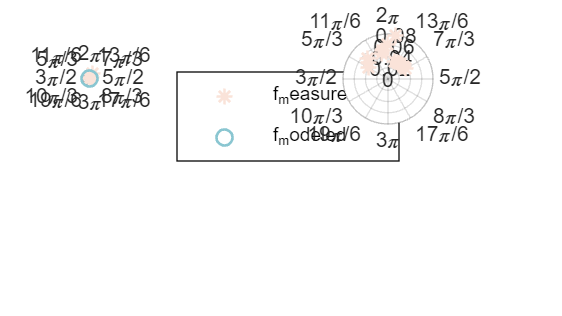

位置 2 处的索引超出数组边界。索引不能超过 58。

%angle
measureangle=x(:,3)';
reflectangle=x(:,4)';

for i = 1:num_leaf
    for j = 1:size(wavelength,1)
        circulation = j+5*(i-1);
        figure(circulation);
        set(gcf,'position',[0,0,1600,900]);
        %1st part
        %When the incident Angle is 0 degrees
        measureangle1=deg2rad(measureangle(1:13));
        reflectangle1=deg2rad(reflectangle(1:13));
        [row_measureangle1,col_measureangle1]=size(measureangle1);
        for l=1:col_measureangle1
            measureangle1(l)=measureangle1(l)-deg2rad(0);
            if measureangle1(l)>deg2rad(90)
                measureangle1(l)=measureangle1(l)-deg2rad(360);
            end
        end
        subplot(2,2,1);
        y1 = result(j,5:17,i);
        point = polarscatter(measureangle1,y1 );
        thetalim([-90 90]); %-90 90
        pax = gca;
        pax.ThetaAxisUnits = 'radians';
        pax.ThetaZeroLocation = 'top';
        pax.ThetaDir = 'clockwise';
        point.MarkerEdgeColor = '#fae3d9';
        point.Marker = '*';
        point.LineWidth = 1.0;
        hold on;
        p1=result(j,43:55,i);
        point = polarscatter(measureangle1,p1 );
        pax = gca;
        pax.ThetaAxisUnits = 'radians';
        pax.ThetaZeroLocation = 'top';
        pax.ThetaDir = 'clockwise';
        point.MarkerEdgeColor = '#8ac6d1';
        point.Marker = 'o';
        point.LineWidth = 1.0;
        legend('f_measured','f_modeled');

        %2st part
        %When the incident Angle is 30 degrees
        reflectangle2 = reflectangle(14:25);
        measureangle2 = deg2rad(measureangle(14:25));
        [row_measureangle2,col_measureangle2]=size(measureangle2);
        for l=1:col_measureangle2
            measureangle2(l)=measureangle2(l)-deg2rad(30);
            if measureangle2(l)>deg2rad(90)
                measureangle2(l)=measureangle2(l)-deg2rad(360);
            end
        end
        subplot(2,2,2);
        y2 = result(j,18:29,i);
        point = polarscatter(measureangle2,y2);
        thetalim([-90 90]); %-90 90
        pax = gca;
        pax.ThetaAxisUnits = 'radians';
        pax.ThetaZeroLocation = 'top';
        pax.ThetaDir = 'clockwise';
        point.MarkerEdgeColor = '#fae3d9';
        point.Marker = '*';
        point.LineWidth = 1.0;
        hold on;
        p2 = result(j,56:67,i);
        point = polarscatter(measureangle2,p2 );
        pax = gca;
        pax.ThetaAxisUnits = 'radians';
        pax.ThetaZeroLocation = 'top';
        pax.ThetaDir = 'clockwise';
        point.MarkerEdgeColor = '#8ac6d1';
        point.Marker = 'o';
        point.LineWidth = 1.0;
        legend('f_measured','f_modeled');

        %3st part
        %When the incident Angle is 55 degrees
        reflectangle3 = reflectangle(26:38);
        measureangle3 = deg2rad(measureangle(26:38));
        [row_measureangle3,col_measureangle3]=size(measureangle3);
        for l=1:col_measureangle3
            measureangle3(l)=measureangle3(l)-deg2rad(55);
            if measureangle3(l)>deg2rad(90)
                measureangle3(l)=measureangle3(l)-deg2rad(360);
            end
        end
        subplot(2,2,3);
        y3 = result(j,30:42,i);
        point = polarscatter(measureangle3,y3);
        thetalim([-90 90]); %-90 90
        pax = gca;
        pax.ThetaAxisUnits = 'radians';
        pax.ThetaZeroLocation = 'top';
        pax.ThetaDir = 'clockwise';
        point.MarkerEdgeColor = '#fae3d9';
        point.Marker = '*';
        point.LineWidth = 1.0;
        hold on;
        p3 = result(j,68:80,i);
        point = polarscatter(measureangle3,p3 );
        pax = gca;
        pax.ThetaAxisUnits = 'radians';
        pax.ThetaZeroLocation = 'top';
        pax.ThetaDir = 'clockwise';
        point.MarkerEdgeColor = '#8ac6d1';
        point.Marker = 'o';
        point.LineWidth = 1.0;
        legend('f_measured','f_modeled');
        %figure
        subplot(2,2,4);
        y_total = [y1,y2,y3];
        p_total = [p1,p2,p3];
        [xData, yData] = prepareCurveData( y_total, p_total );
        % 设置 fittype 和选项。
        ft = fittype( 'poly1' );
        % 对数据进行模型拟合。
        [fitresult, gof] = fit( xData, yData, ft );
        % 绘制数据拟合图。
        h = plot( fitresult, xData, yData );
        legend( h, 'data', 'fitting curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
        % 为坐标区加标签
        xlabel( 'f_measured', 'Interpreter', 'none' );
        ylabel( 'f_modeled', 'Interpreter', 'none' );
        grid on
        %print
        picname=strcat(leaf,'-',surface,'-',num2str(i),'-',num2str(j));
        print(gcf, '-djpeg', [picname,'.jpg']);
        %%打印y和p数值

    end
end

close all;

补充：函数库

1st，向量内积（角度制）

function angle = vAngle(A,B)
angle = acosd(sum(A.*B)/(sqrt(sum(A.*A))*sqrt(sum(B.*B))));
end

2st，F菲涅尔系数（代表物体表面的镜面反射率，是入射角和波长的函数）


$$F=\frac{1}{2}{\left(\frac{n^2 +\cos^2 \left(\theta \right)-1-\cos \left(\theta \right)}{n^2 +\cos^2 \left(\theta \right)-1+\cos \left(\theta \right)}\right)}^2 \left\lbrack 1+{\left(\frac{\cos \left(\theta \right)\left(n^2 +\cos^2 \left(\theta \right)-1+\cos \left(\theta \right)\right)-1}{\cos \left(\theta \right)\left(n^2 +\cos^2 \left(\theta \right)-1-\cos \left(\theta \right)\right)+1}\right)}^2 \right\rbrack$$


%F(n,θh) is the Fresnel term for dielectric materials characterized by the refraction index, n, and for non-polarized incident light 

%Fresnel, 1868; Sparrow & Cess, 1978

function f = F_factor(theta, n)
ct = cosd(theta);
g = n * n + ct * ct - 1;
f = 0.5 * power((g - ct) / (g + ct), 2) * (1 +  power( (ct*(g+ ct)-1) / (ct*(g-ct)+1) ,2) );
%  Equation from Bousquet L et al (2005) Remote Sens Environ 98: 201–211
end

3st，D为微面元斜率分布函数，由Beekinan分布函数描述


$$D=\frac{1}{\rho^2 \cos^4 \left(\alpha \right)}e^{-{\left\lbrack \frac{\tan \left(\alpha \right)}{\rho }\right\rbrack }^2 }$$


function d = D_factor(a,rho)
% D, facet slope distribution function, depending on the roughness parameter, use Beckmann distribution function
% Beckmann Petr and Spizzichino Andre, The Scattering of Electromagnetic Waves from Rough Surfaces, MacMillan, pp.1-33, 70-98, 1963.
%rho为微面元斜率分布均方差,代表表面粗糙度
%a为表面和刻面元法线夹角,from Cook 1981, computer graphics
d = exp(-power(tand(a) / rho, 2)) / (rho * rho * power(cosd(a), 4)) ; % D depends on the roughness parameter BRDF_rho, ousquet et al 2005.
% BRDF_m from 0.1 or small to 0.7 tested. we get, when a is 0, the D is maximal
end

4st，G几何衰减因子（代表微面元遮挡入射光和反射光引起的几何衰减）


$$G=\min \left\lbrace 1,\frac{2\left(N,H\right)\left(N,V\right)}{\left(V,H\right)},\frac{2\left(N,H\right)\left(N,L\right)}{\left(V,H\right)}\right\rbrace$$


% Blinn (1977) shadowing/masking factor.

%cook-Torrance model

function g = G_factor(L,N,V,H)
% G, geometrical attenuation factor, accouting for the shadowing and masking of one facet by another.
G1 = 2 * sum(N .* H) * sum(N .* V) / sum(V .* H);
G2 = 2 * sum(N .* H) * sum(N .* L) / sum(V .* H);
g = min(1, min(G1, G2));  % only depends on the incident and reflect ray directions.
% G is 1 when the reflect direction is close to the mirror reflect direction.
% when the reflect direction is far from the mirror reflect direction, it can be less than 1.
end

5st，BRDF计算公式


$$\textrm{BRDF}=R_s +R_d =\frac{F\;D\;G}{{2\pi }^2 \left(L,N\right)\left(N,V\right)}+\frac{K}{\pi }$$


function f = brdffunction (canshu,x)
%数据转换
BRDF_rho = canshu(1);
BRDF_k = canshu(2);
BRDF_n = canshu(3);
f = zeros(1,size(x,1));
for i = 1:size(x,1)
    L = x(i,7:9);
    N = x(i,10:12);
    V = x(i,13:15);
    H = x(i,16:18);
    theta = vAngle(L,H);%入射方向和刻面法向的夹角
    alpha = x(i,6);%表面和刻面法向的夹角
    %计算F、D、G因子
    F = F_factor(theta,BRDF_n);
    D = D_factor(alpha,BRDF_rho);
    G = G_factor(L,N,V,H);
    %     f(i) =(F*D*G/((2*pi*pi)*(sum(L.*N)*sum(N.*V)))+BRDF_k/pi)*cosd(x(i,4));
    f(i) =(F*D*G/((2*pi*pi)*(sum(L.*N)*sum(N.*V)))+BRDF_k/pi);
    % Eqn 3.2, in Xu W. and Lao Cailian Analysis of scattering characteristic of the maize leaves based on BRDF model
end
end